## TOPSIS 法

1.可翻译为逼近理想解排序法，国内常简称为优劣解距离法

2.极大型指标（效益型指标）， 极小型指标（成本型指标），中间型，区间型

3.指标正向化：将所有的指标都转化为及大型（最常用）

4.步骤

        A.转化成极大型：

        

        中间型

        

        区间型

        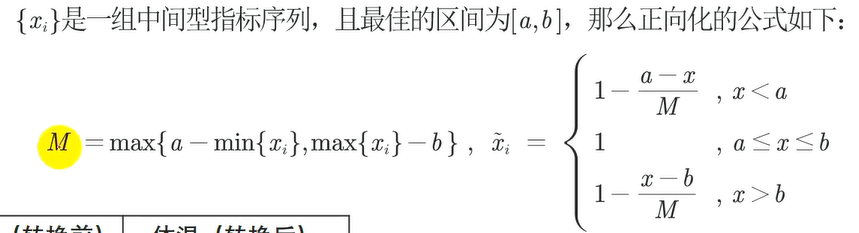

        A.标准化：

        每一个元素 / 所在列的平方和的根号

        

## 程序

1.共有 TOPSIS.mlx 和 top_interval.m 两个文件

2.此程序只需更改 A   A_flag   A_data_mid   A_data_interval 四个矩阵即可

clc
clear

%    含氧量  PH值  细菌总数  植物营养物量
A = [4.69	6.59	51	 11.94;
     2.03	7.86	19	 6.46;
     9.11	6.31	46	 8.91;
     8.61	7.05	46	 26.43;
     7.13	6.5	    50	 23.57;
     2.39	6.77	38	 24.62;
     7.69	6.79	38	 6.01;
     9.3	6.81	27	 31.57;
     5.45	7.62	5	 18.46;
     6.19	7.27	17	 7.51;
     7.93	7.53	9	 6.52;
     4.4	7.28	17	 25.3;
     7.46	8.24	23	 14.42;
     2.01	5.55	47	 26.31;
     2.04	6.4	    23	 17.91;
     7.73	6.14	52	 15.72;
     6.35	7.58	25	 29.46;
     8.29	8.41	39	 12.02;
     3.54	7.27	54	 3.16;
     7.44	6.26	8	 28.41];
 
 % B 用于标记 A 中对应列所需的处理
 % 0--极大型  1--极小型  2--中间型  3--区间型
 A_flag = [0 2 1 3];
 A_data_mid = 7;   % 中间型的最佳数值
 A_data_interval = [10 20];  % 区间型的最佳数值
 [A_r, A_c] = size(A);
 A_weight = zeros(1, A_c);
 A_weight(:) = 1 / A_c;  % 权重，默认为 1 / A_c, 即无权重
 
 % 检测权重之和是否为 1
 A_weight_data = 0.0;
 for i = 1 : A_c
     A_weight_data = A_weight_data + A_weight(i);
 end
 
 if A_weight_data ~= 1
    disp('错误！ 权重之和不等于 1 ！\n')
 end

 
 % 正向化
 A_data_mid_flag = 1;
 A_data_interval_flag = 1;
 for i = 1 : A_c
     switch A_flag(i)
         case 0
             
         case 1
             A(:, i) = max(A(:, i)) - A(:, i);
         case 2
             A(:, i) = 1 - abs(A(:, i) - A_data_mid) / max(abs(A(:, i) - A_data_mid));
             A_data_mid_flag = A_data_mid_flag + 1;
         case 3
             A(:, i) = top_interval(A(:, i), A_data_interval(A_data_interval_flag, 1), A_data_interval(A_data_interval_flag, 2));
             %A(:, i) = top_interval(A(:, i), 10, 20)
             A_data_interval_flag = A_data_interval_flag + 1;
         otherwise
             disp('A_flag值错误！\n')
     end
 end

函数或变量 'top_interval' 无法识别。

 B = A
 
 
% 标准化
A_sum = sum(A .* A);  % 按列平方相加
A_sort = A_sum .^ (1/2);  % 矩阵内各元素开根号
A_standard = A ./ repmat(A_sort, A_r, 1);  % 标准化
disp('标准化矩阵：')
disp(A_standard)


% 计算得分
A_weight = repmat(A_weight, A_r, 1);
top_man = sum([(A_standard - repmat(max(A_standard), A_r, 1)) .^ 2], 2) .* A_weight .^ 0.5;   % D+ 与最大值的距离向量
top_min = sum([(A_standard - repmat(min(A_standard), A_r, 1)) .^ 2], 2) .* A_weight .^ 0.5;   % D- 与最小值的距离向量
top_s = top_min ./ (top_man + top_min)  % 未归一化的得分
top_stand = top_s / sum(top_s);
disp('得分')
disp(top_stand)

% 降序排序（descend） sorted_s--top_stand降序排序所得  index--对应的位置
[sorted_s, index] = sort(top_stand, 'descend')  